# EE525 - Lab Project 1

Authors: Grant Gallagher, Alexander Goldstein, Yu-Shun Hsiao, Jacobis, Soriano Pelaez

Due: 10/8/2021

Objective:

## Initialization

This section of code is used to clear the workspace of all variables and figures, so that the program can be run from scratch.

clc;    % Clear command window
clear;  % Clear all variables from workspace
clf;    % Clear all figures

## 1. Digital Communications

### Problem Statement

In a phase-shift keyed (**PSK**) digital communication system,  a binary digit (also termed a bit), which is either a “**0**” or a “**1**”, is communicated to a receiver by sending either$s_0 =\mathrm{Acos}\left(2\pi F_0 t+\pi \;\right)$ to represent a “0” or $s_1 =\textrm{Acos}\left(2\pi F_0 t\;\right)$ to represent a “1”, where $A>0$. The receiver that is used to decode the transmission is shown in the figure below. The receiver that is used to decode the transmission is shown in the figure below. 

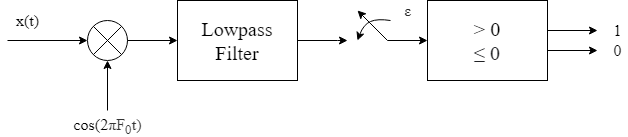

The input to the receiver is the noise corrupted signal or $x\left(t\right)=s_i \left(t\right)+w\left(t\right)$, where $w\left(t\right)$ represents the channel noise. It can be shown that in the absence of noise, the output of the lowpass filter is


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2} & \mathrm{for}\;a\;"0"\\
\frac{A}{2} & \mathrm{for}\;a\;"1"
\end{array}\right.$$


The receiver decides a "1" was transmitted if $\zeta >0$ and a "0" if $\zeta \le 0$. To model the channel noise we assume that the actual value of $\zeta$ observed is


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2}+W & \mathrm{for}\;a\;"0"\\
\frac{A}{2}+W & \mathrm{for}\;a\;"1"
\end{array}\right.$$


where $W$ is the Gaussian random variable, $W~N\left(0,1\right)$.

- Analytically determine the probability of error $P_e$, and plot it versus $A$.

- Use computer simulation to plot $P_e$ versus $A$ on the same graph as in 1 above.

- How should one choose $A$ so that the error probability does not exceed 0.01 (use the analytical result)? 

### 1.1 Analytical Solution

The first goal is to analytically determine the probability of error $P_e$, and plot it versus $A$. First, we will declare the symbolic variables of the system, where A is the signal amplitude, W is the channel noise, and x is a generic variable. Then, we initialize the probabilities of a 0 or 1 is being sent.

syms A W x
P_0 = 0.5; % Probability that a "0" is sent
P_1 = 0.5; % Probability that a "1" is sent

Next, we declare the function of the Normal Gaussian Distribution which has the form of,


$$f\left(x\right)=\frac{1}{\sqrt{2\pi \;}}e^{\left(-\frac{x^2 }{2}\right)}$$


and substitute our signal functions (with noise) for the variable $x$.

Guass_Norm_pdf = 1/sqrt(2*pi) * exp((-(x)^2)/2); % Normal Gaussian Distribution func.

Zeta_0_pdf = subs(Guass_Norm_pdf, x, (A/2 + W)); % PDF of a "0" being read
Zeta_1_pdf = subs(Guass_Norm_pdf, x, (A/2 - W)); % PDF of a "1" being read

This yeilds the following two results for the probability distributions of a "0" or "1" being sent,


$$f_{c,0} =\frac{1}{\sqrt{2\pi \;}}e^{\left(-\frac{{\left(-\frac{A}{2}+w\right)}^2 }{2}\right)} ,\;\;\;\;\;\mathrm{for}\;\mathrm{a}\;\mathrm{"0"}$$



$$f_{c,0} =\frac{1}{\sqrt{2\pi \;}}e^{\left(-\frac{{\left(\frac{A}{2}+w\right)}^2 }{2}\right)} ,\;\;\;\;\;\mathrm{for}\;\mathrm{a}\;\mathrm{"1"}$$


Subsequently, the cdf, or probability of error given that the input is a "0" or "1" can be calculated by integration


$$P\left(\mathrm{error}|0\right)=1-\int_{-\infty \;}^{0\;} f_0 \left(w\right)\mathrm{dw}$$



$$P\left(\mathrm{error}\left|1\right.\right)=\int_{-\infty }^0 f_1 \left(w\right)\mathrm{dw}$$


P_e_given_0 = 1 - int(Zeta_0_pdf,W,-inf,0); % CDF of an error given a "0"
P_e_given_1 = int(Zeta_1_pdf,W,-inf,0);     % CDF of an error given a "1"

Finally, the analytical solution to the total probability of error as a function of A can be expressed as


$$P_e =P\left(\mathrm{error}\left|0\right.\right)\left(P\left(0\right)\right)+P\left(\mathrm{error}\left|1\right.\right)\left(P\left(1\right)\right)$$


P_e_analytical = vpa((P_e_given_0*P_0 + P_e_given_1*P_1), 4) % Probability of error as func. of A

$$P\_e\_analytical = 0.5-0.5\,\mathrm{erf}\left(0.3536\,A\right)$$

However, this result can be expressed in a more neat manner as follows,


$$P_e =\frac{1}{2}\left(1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right)$$


### 1.2 Computer Simulation

The second goal is use a computer simulation to plot $P_e$ versus $A$ on the same graph as in 1 above. First, we declare the range of values of $A$ that we would like to use.

Astep = 20;                         % Step size of A values
Aspan = [0, 5];                 % The minimum and maximum values for A
A_values = [Aspan(1):range(Aspan)/Astep:Aspan(2)];  % The array of A values
errors = zeros(length(A_values), 1);   % An empty matrix containing the
                                % simulated number of errors for given A value

Then, we calculate the percent of error for each value of $A$, for n number of samples. First, we calculate the probability of error $P_e$ as a function of signal amplitude $A$ for sample sizes of 100.

n = 1000; % Sample Size     
% Iterate through each value of A                             
for k = 1:length(A_values)
    dist = normrnd(A_values(k)/2, 1, [1 n]); % Distribution of read values for A
    % Iterate through each sample of read values.
    for m = 1:n
        % Determine if the received value is an error
        if dist(m) <= 0
            errors(k) = errors(k) + 1; % Count the number of errors.\
        end
    end
end

P_e_simulation = errors/n; % Probability of error vs A

Finally, we can plot the results.

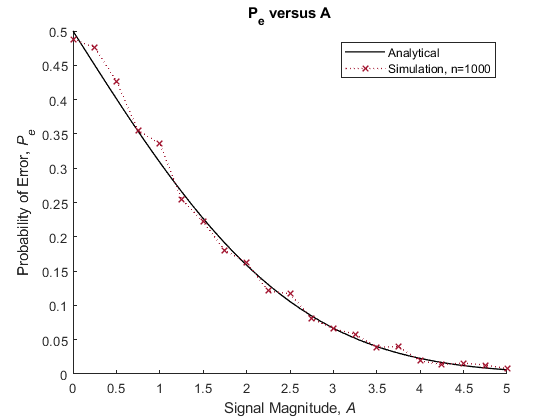

fig1 = figure; % Create a new figure
hold on
% Plot the analytical solution
fplot(P_e_analytical, '-', 'Color', [0 0 0] ...
                         , 'LineWidth', 1 ...
                         , "XRange", [0 5])

% Plot the simulation for n=100 
plot(A_values, P_e_simulation, ':', 'Color', [0.6350 0.0780 0.1840] ...
                                  , 'LineWidth', 1 ...
                                  , 'Marker', 'x')
hold off

% Label the graph appropriately
legend('Analytical', 'Simulation, n=1000')
title("P_e versus A")
xlabel("Signal Magnitude, {\itA}  ")
ylabel("Probability of Error, {\itP_e}")

shg % Show the Figure

From the plot above, we can see the the numerical and analytical solutions agree with one another.

From the trend, we can see that the probability of error,$P_e$, *decreases* for large values of $A$. This is expected, as if we increase the magnitude of the input the signal, $A$, the effect of the that the random Gaussian noise, $W$, has on the signal decreases. As the limit of the magnitude of the input signal approaches infinity, the probability of a error goes to zero.


$$\underset{A\to \infty \;}{\mathrm{lim}} P_e \left(A\right)=0$$


Perhaps the most interesting feature of this plot is the probability of error when $A$ is equal to zero (no purposeful signal). We can see that the expected value of error approaches 0.5. At this point, the probability of error has the same distribution as the random variable, $W$, which is a Normal Guassian distribution (centered at 0 with a standard deviation of 1).

### 1.3 Discussion

Q: How should one choose $A$ so that the error probability does not exceed 0.01 (use the analytical result)?

In order to choose a value of A such that the error probability does not exceed 0.01, the normal cdf can be used. This desired result can be expressed by the following equation,


$$P_e \left(A\right)\le 0\ldotp 01$$


where the probability of error for a value of $A$ can be expressed by the solution in part 1.1,


$$\frac{1}{2}\left(1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right)\le 0\ldotp 01$$


then, multiplying both sides by 2


$$1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\le 0\ldotp 02$$


then, subtracting 1 from both sides while keeping $A$ on the left hand side,


$$\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\le 0\ldotp 98$$


and taking the inverse error function of both sides,


$$\frac{\sqrt{2}}{4}A\le {\mathrm{erf}}^{-1} \left(0\ldotp 98\right)$$


isolating A to the left hand side of the equation


$$A\le 2\sqrt{2}{\mathrm{erf}}^{-1} \left(0\ldotp 98\right)$$


and finally, evaluting the inverse error function and square root for the numerical approximation,


$$A\ge 4\ldotp 653$$


Likewise, this analytical solution can be solved simply by the following line of code,

A_min = vpa(solve(0.01 == P_e_analytical,A), 4) % Minimum value of A such P_e <= 0.01

$$A\_min = 4.653$$

Graphically, we can show this point by drawing a line at $P_e$ is equal to 0.01, and finding the corresponding signal magnitude, $A$, on the plot.

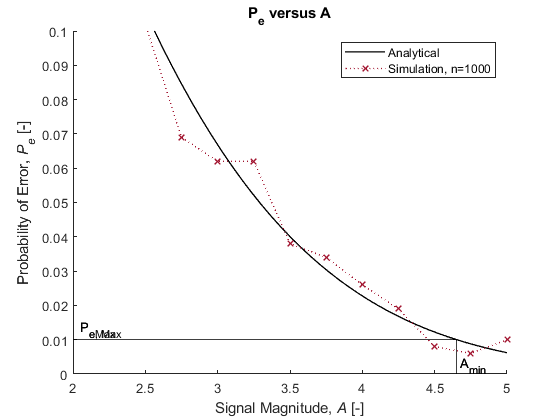

fig2 = fig1;
hold on
plot([double(A_min), double(A_min)], [0, 0.01], 'Color', [0 0 0])
plot([0, double(A_min)], [0.01 0.01], 'Color', [0 0 0])
text(2.05, 0.013, 'P_{e, Max}')
text(double(A_min)+0.02, 0.0025, 'A_{min}')
xlim([2 5])
ylim([0 0.1])
legend('Analytical', 'Simulation, n=1000')

## Part 2. COVID-19 Data Analysis

### Problem Statement

In this assignment, you will analyze the data to understand the Coronavirus pandemic, in particular, you will study the factors that might impact the mortality rate of COVID-19. You can find the dataset provided by *Our World in Data* [here](https://github.com/owid/covid-19-data/tree/master/public/data). It provides daily numbers on confirmed cases and deaths, testings, vaccinations, and other metrics for over 100 countries. For this study, consider the following data: *new_deaths_per_million* for the month of September 2021, *new_tests_per_thousand* for the same period, *people_vaccinated_per_hundred*, *aged_70_older*, *gdp_per_capita, cardiovasc_death_rate, diabetes_prevalence*. If a country misses any of the data, remove that country in this study.

- Plot the distribution of death rates for all countries. Compute the average death rates and the variance (Don’t use MATLAB built-in functions). What do these numbers tell us? Describe anything else you observe from the data.

- Study all other metrics. Plot their distributions, compute and interpret the average values and variances.

- Compute the correlation coefficients between the death rates and other metrics. What factor(s) affect the mortality rate the most? Plot the scatter diagram to support your argument. Describe anything else you observe from the data.

### Import and Filtering Data

First, we must import the most recent data from the file of comma separated variables.

raw_covid_data = readtable('owid-covid-data.csv'); % Table of raw covid data

Next, we can identify a list of unique country names

unique_countries = unique(raw_covid_data.location); % Unique country names

Now comes the tricky part. For this study, we reject all countries that miss any of the data. That is, each country must have a at least one distinct value for every random variable under consideration. To do this, we create an empty array which will contain the values of all unique countries that fit this rule. Next, check whether the country has at least one data point for every random variable. If the country does not contain an empty or null array of values for each random variable, we accept it and append it to a list of countries which fit this category.

countries = cell(1);
% Aquire data for each country with valid data
for k = 1:length(unique_countries)
    % Filter by month and valid values
    if or(isempty(raw_covid_data.new_deaths_per_million( ...
            ...
            string(raw_covid_data.location) == unique_countries(k) ...
                ...
                & raw_covid_data.date >= '1-Sep-2021' ...
                & raw_covid_data.date <= '30-Sep-2021')) ...
       , all(isnan(raw_covid_data.new_deaths_per_million( ...
            string(raw_covid_data.location) == unique_countries(k) ...
                & raw_covid_data.date >= '1-Sep-2021' ...
                & raw_covid_data.date <= '30-Sep-2021'))))
        continue
    % Filter by month and valid values                                    
    elseif or(isempty(raw_covid_data.new_tests_per_thousand(string(raw_covid_data.location) == unique_countries(k) ...
                                                     & raw_covid_data.date >= '1-Sep-2021' ...
                                                     & raw_covid_data.date <= '30-Sep-2021')) ...
           , all(isnan(raw_covid_data.new_tests_per_thousand(string(raw_covid_data.location) == unique_countries(k) ...
                                                     & raw_covid_data.date >= '1-Sep-2021' ...
                                                     & raw_covid_data.date <= '30-Sep-2021'))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.people_vaccinated_per_hundred( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.people_vaccinated_per_hundred( ...
                string(raw_covid_data.location) == unique_countries(k))))
       continue 
    % Filter by valid values   
    elseif or(isempty(raw_covid_data.aged_70_older( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.aged_70_older( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values    
    elseif or(isempty(raw_covid_data.gdp_per_capita( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.gdp_per_capita( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.cardiovasc_death_rate( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.cardiovasc_death_rate( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.diabetes_prevalence( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.diabetes_prevalence( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    end
    % Append country name to list of countries with valid data
    countries(end+1,1) = unique_countries(k);
end
countries = string(countries(2:end)); % Remove the first, null index

Now, we have a list of countries which contain data for each random variable under consideration.

### 2.1 Distribution of Death Rates

Before we plot the distribution of death rates for all countries, we first determine the distribution of death rates for each country. For each country, we take the *average* death rates per million people. This gives us a distribution of average death rates per million people per country. Subsequently, the average value value of death rates per country is equal to the total average death rates.

Since we will be aquiring the distribution of other random variables, we can condense the collection of these distribution into a single **for** loop. First, we initialize empty arrays for each variable which are the lengths of the number of country. Thus, the total collection of variables per country makes up our distribution of random variables.

% Distributions of random variables
dist_avg_deaths_per_million = zeros(length(countries), 1);
dist_avg_tests_per_thousand = zeros(length(countries), 1);
dist_people_vaccinated_per_hundred = zeros(length(countries), 1);
dist_avg_aged_70_older = zeros(length(countries), 1);
dist_avg_gdp_per_capita = zeros(length(countries), 1);
dist_avg_cardiovasc_death_rate = zeros(length(countries), 1);
dist_avg_diabetes_prevalence = zeros(length(countries), 1);

One important point to note is that we will be computing the average (expected) value of *each* random variable for each country.

for k = 1:length(countries)
    new_deaths_per_million = raw_covid_data.new_deaths_per_million( ...
                                string(raw_covid_data.location) == countries(k) ...
                                & raw_covid_data.date >= '1-Sep-2021' ...
                                & raw_covid_data.date <= '30-Sep-2021' ...
                                & ~isnan(raw_covid_data.new_deaths_per_million));
                                        
    new_tests_per_thousand = raw_covid_data.new_tests_per_thousand( ...
                                string(raw_covid_data.location) == countries(k) ...
                                & raw_covid_data.date >= '1-Sep-2021' ...
                                & raw_covid_data.date <= '30-Sep-2021' ...
                                & ~isnan(raw_covid_data.new_tests_per_thousand));
                            
    dist_people_vaccinated_per_hundred(k) = max(raw_covid_data.people_vaccinated_per_hundred( ...
                                         string(raw_covid_data.location) == countries(k) ...
                                         & ~isnan(raw_covid_data.people_vaccinated_per_hundred)));
     
    aged_70_older = raw_covid_data.aged_70_older( ...
                    string(raw_covid_data.location) == countries(k) ...
                    & ~isnan(raw_covid_data.aged_70_older));
                                
    gdp_per_capita = raw_covid_data.gdp_per_capita( ...
                     string(raw_covid_data.location) == countries(k) ...
                     & ~isnan(raw_covid_data.gdp_per_capita));
    
    cardiovasc_death_rate = raw_covid_data.cardiovasc_death_rate( ...
                            string(raw_covid_data.location) == countries(k) ...
                            & ~isnan(raw_covid_data.cardiovasc_death_rate));
    
    diabetes_prevalence = raw_covid_data.diabetes_prevalence( ...
                          string(raw_covid_data.location) == countries(k) ...
                          & ~isnan(raw_covid_data.diabetes_prevalence));
    
    
    dist_avg_deaths_per_million(k) = first_moment(new_deaths_per_million);
    dist_avg_tests_per_thousand(k) = first_moment(new_tests_per_thousand);
    dist_avg_aged_70_older(k) = first_moment(aged_70_older);
    dist_avg_gdp_per_capita(k) = first_moment(gdp_per_capita);
    dist_avg_cardiovasc_death_rate(k) = first_moment(cardiovasc_death_rate);
    dist_avg_diabetes_prevalence(k) = first_moment(diabetes_prevalence);
end

distributions = [dist_avg_deaths_per_million, dist_avg_tests_per_thousand, dist_people_vaccinated_per_hundred, ...
                 dist_avg_aged_70_older, dist_avg_gdp_per_capita, dist_avg_cardiovasc_death_rate, dist_avg_diabetes_prevalence];
random_variable_names = {'Avg. New Deaths per Million', 'Avg. New Tests per Thousand', 'People Vaccinated Per Hundred', ...
                         'Avg. Aged 70 or Older', 'Avg. GDP per Capita', 'Avg. Cardiocascular Death Rate', 'Avg. Diabetes Prevalence'};
                     
table_distributions = array2table(distributions, 'RowNames',countries, ...
                                     'VariableNames', random_variable_names)

### Part 1. Death Rates in September

fig3 = figure
histogram(dist_avg_deaths_per_million, round(sqrt(length(countries))))
title('Average new death rates per million by country for the month of September')
ylabel('Number of countries')
xlabel('Avg. New deaths per million')

### Part 2. Analysis of Other Metrics

fig4 = figure
set(gcf, 'position', [0 0 800 500])
subplot(2, 3, 1)
histogram(table_distributions.("Avg. New Tests per Thousand"), round(sqrt(length(countries))))
xlabel('Avg. New Tests per Thousand')
ylabel('# of Countries')
subplot(2, 3, 2)
histogram(table_distributions.("People Vaccinated Per Hundred"), round(sqrt(length(countries))))
xlabel('Vaccinated Per Hundred')
ylabel('# of Countries')
subplot(2, 3, 3)
histogram(table_distributions.("Avg. Aged 70 or Older"), round(sqrt(length(countries))))
xlabel('Avg. Aged 70 or Older')
ylabel('# of Countries')
subplot(2, 3, 4)
histogram(table_distributions.("Avg. GDP per Capita"), round(sqrt(length(countries))))
xlabel('Avg. GDP per Capita')
ylabel('# of Countries')
subplot(2, 3, 5)
histogram(table_distributions.("Avg. Cardiocascular Death Rate"), round(sqrt(length(countries))))
xlabel('Avg. Cardiocascular Death Rate')
ylabel('# of Countries')
subplot(2, 3, 6)
histogram(table_distributions.("Avg. Diabetes Prevalence"), round(sqrt(length(countries))))
xlabel('Avg. Diabetes Prevalence')
ylabel('# of Countries')
table_averages = array2table(first_moment(table_distributions), 'RowNames', {'Global Average'}, ...
                                                                'VariableNames', random_variable_names)
table_variences = array2table(second_moment(table_distributions), 'RowNames', {'Global Varience'}, ...
                                                            'VariableNames', random_variable_names)